# Plotting 

There are 4 main elements used to explore and visualise synaptic point clouds and analysis results:

- **Point clouds** : plot different groups of synapses as point clouds , representing each synapse as a point in 3D.

- **Voxels** : plot statistic per voxel (for example the number of gained synapses in a voxel, or the difference between the number of  lost and gained synapses)

- **DB-plane** : plot DB plane in 3D. 

- **Template** fish image : plot the image of the template fish to put everything else into the context.

Currently, only **Point clouds** work for single entries, that have not been registered. More possibilities on the way!  For convenience, there are some helper functions at the end of the file, you can change them if you would like. 

*This script is using **stu**,**syn** prodused by the **ImportSingleEntry**. 

## load utility functions

cd 'D:\Code\repos\synapse-redistribution\data_vizualization'
addpath('utils');

## Plot Point Clouds

Here is an example how to plot a point cloud that consists only of gained synapses. You need to set the fish (or group of fish) for which to plot synapses. 

Here we are plotting the synapses of the first fish in the Learners group only: 

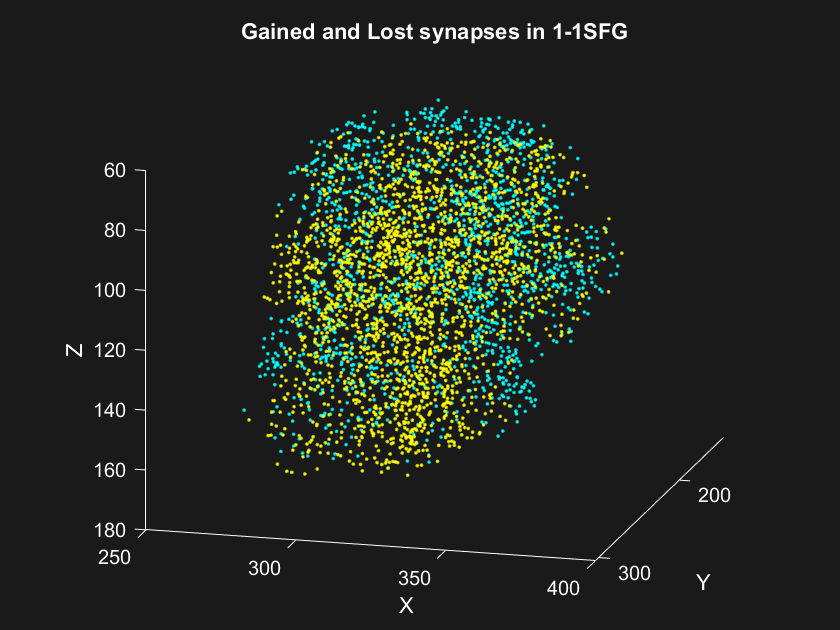

subject_id = stu.Id.Unassigned{1};
i_fish = stu.Unassigned(1);

% gained&lost pointcloud in dorsal space 
pointCloud_ga = syn.gained.xyz_anat{i_fish};
pointCloud_lo = syn.lost.xyz_anat{i_fish};
figure;
% plot point clouds of the lost and gained synapses
plot_ptc(pointCloud_ga,'Color',[1 1 0],'MarkerSize',5);
hold on 
plot_ptc(pointCloud_lo,'Color',[0 1 1],'MarkerSize',5);

title(['Gained and Lost synapses in ',subject_id],'Color',[1 1 1]);
axisProperties

## DB Plane for a single entry

To get an unbiased statistics of the spatial distribution of the lost and the gained synapses, in the main analysis pipeline we are calculating DB plane using a leave-one-out approach. However when exploring the data, you might want to calculate a DB plane of an individual dataset.

Calculate a DB-plane that separates the points in the two provided pointclouds: gained (pointCloud_ga) and lost (pointCloud_lo) synapses:

% number of samples to use ( to correct for bias):
nSamples = min(length(pointCloud_lo),length(pointCloud_ga));

% load db-plane util functions
db_plane_folder = fullfile(fileparts(pwd),'data_analysis','db_plane','utils');
addpath(db_plane_folder);

% calculate db-plane
db = getDecisionBoundaryFromPointCloud(pointCloud_ga,pointCloud_lo,nSamples);

## Plot Over Template Image 

Load the template image to show in the background and specify the image resolution. All fish have been regestered to this template image. The high-resolution template image ( xyz resolution [0.26 0.26 0.4] ) is part of the [Dataset: 1-1GNP](https://synapse.isrd.isi.edu/chaise/record/#1/Zebrafish:Cohort/RID=1-1GNP) with the RID : 1-0ZBG ( Image_1-0ZBG.ome.tif ). However here we are using a downsampled version of the image with resolution [0.52 0.52 0.4] RID : 1-1S1W ( Image_1-1S1W.ome.tiff ) .

Provide path to file and resolution. 

imageFile = 'data\Image_1-1S1W.ome.tiff';
% imageFile = output_file;
% imageFile = 'D:\Code\repos\synapse-redistribution\registration\data\gab1b\gad1b_images\Image_1-1RSE_odd_slices.tif';
% img_res = [0.1563 0.1563 0.4463];
img_res = [0.52 0.52 0.4]; 

% read the file
Img = read_tiff3d(imageFile,0,[],[]);

Choose db :

cl = db.Learners.number.mean

cl = struct with fields:
    Beta: [3×1 double]
    Bias: -8.7493
    flip: 0


Plot :

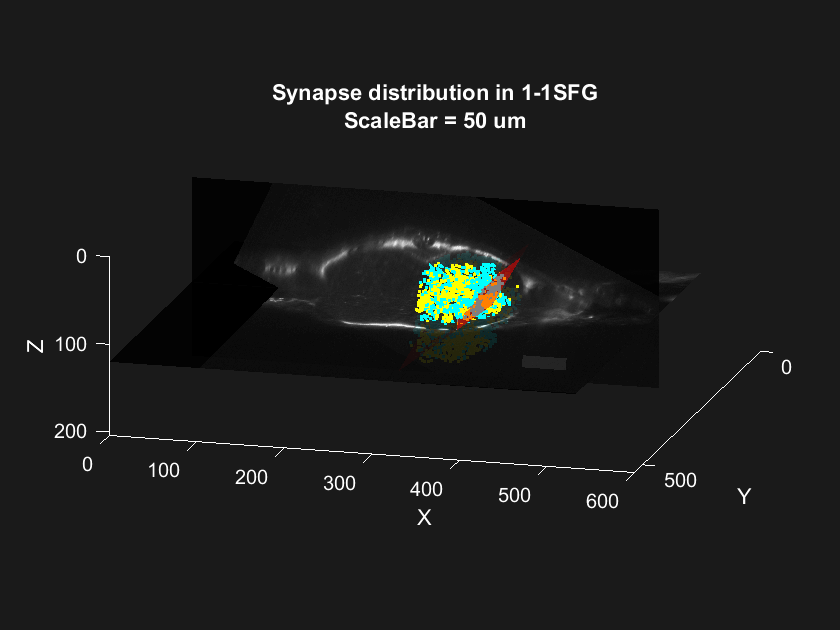

figure;
% plot two image slices (in xy and xz planes )
zSlice = 120; % um
ySlice = 180; % um
plotImageSlice(Img,img_res,"xy",zSlice);
hold on
plotImageSlice(Img,img_res,"xz",ySlice);
hold on
% plot point clouds of the lost and gained synapses
plot_ptc(pointCloud_lo,'Color',[0 1 1],'MarkerSize',5);
hold on
plot_ptc(pointCloud_ga,'Color',[1 1 0],'MarkerSize',5);
hold on
% plot DB-plane
plotDecisionBoundary([pointCloud_ga;pointCloud_lo],cl,'Color',[1 0 0],'FaceAlpha',0.5);
hold on
% plot scale bar
scalebar_length = 50;
plot_scalebar(scalebar_length,[420,340,zSlice+20]);

title({['Synapse distribution in ',subject_id];['ScaleBar = ',num2str(scalebar_length),' um']},'Color',[1 1 1]);

axisProperties

## Helper functions 

These are two functions: one sets the axis properties and another one draws a scale bar. They are helpful to save space when plotting, feel free to change them to your liking.

function axisProperties
% sets the axis limits, direction, labels and figure colors and default view
    xAxisLim = [0 510];
    yAxisLim = [0 350];
    zAxisLim = [-50 300];
    
    daspect([1 1 1])
    set(gca,'Zdir','reverse')
    set(gca,'Xdir','reverse')
    
    set(gca,'color',[0.1 0.1 0.1])
    set(gcf,'color',[0.1 0.1 0.1])
    set(gca,'XColor',[1 1 1],'YColor',[1 1 1],'ZColor',[1 1 1]);
    grid off
    box off
    
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    
% limis are commented out, uncomment if you'd like 
    %xlim(xAxisLim);
    %ylim(yAxisLim);
    %zlim(zAxisLim);
    
    % rotate to dorsal view:
    %view(180,90);
    
    % arbitrary angle in 3D:
    view([-165 15])

end


function plot_scalebar(length,position)
% plots a scalebar of the given size (in microns) 
% at position (in 3D : x,y,z ,in microns)
    scaleBarX = position(1);
    sbWidth = length; 
    scaleBarY = position(2); 
    scaleBarZ = position(3); 
    
    plot3([scaleBarX,scaleBarX+sbWidth],[scaleBarY scaleBarY],[scaleBarZ scaleBarZ],...
        '-','Color',[1 1 1],'LineWidth',6);
end